## Regresión Lineal cuenca del Río Pánuco

### NDVI del año 2000 al 2022

### 1.- Inicialización de la información

Imports y declaración de variables

import matlab.io.hdfeos.*

clearvars -except area_estudio;
close all;

Declaracón de variables como directorio de datos, latitud y longitud del área de estudio y posición en las cuadriculas de MODIS. 

declaraciones

>>> Declarando variables...ok


Variables para realizar seguimiento del código y mostrar más mensajes y/o mapas. Tiempo de pausa en segundos.

debug_pausa = 2; %tiempo de pausa de imagenes
debug_dibujar_mapa = false;  %dibujar los mapas 

Leer todos los archivos de la zona de estudio y guardar la información en una tabla

| idx | diaj | dia | mes | estación | año | v6 | v7 | calidad |

%% obtener la info del área de estudio
[lat,lon,ndvi] = m_leer_dir_hdfs(dir_data,coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

>>>>> Obteniendo la zona de estudio
>>>>> Analizando 2 archivos


info_hdf = m_infohdfs2table(dir_data);

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1042 archivos


Matriz que delimita el área de estudio. Se carga de archivo "area_estudio.mat". Sino existe. Lo crea. El proceso puede tardar un rato

ae = exist("area_estudio","var");
if ae == 0
    ae = exist("area_estudio.mat","file");
    if ae == 2
        disp(">>> Cargando área de estudio");
        load area_estudio;
    else
        area_estudio = m_crear_area_estudio(dir_data+'KML\RH26.kml',lat,lon);
        
    end
else
    if( numel(area_estudio) <= 1)
        disp("La variable area_estudio sera sustituida");
        area_estudio = m_crear_area_estudio(dir_data+'KML\RH26.kml',lat,lon);
    end
end

Pixeles en total del área de estudio

calidad_total = sum(area_estudio,"all");

Dibujar mapa de prueba de lectura de datos

% if debug_dibujar_mapa == true
%     ndvi(area_estudio==false)=NaN;
%     m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ndvi,"NDVI TEST",[],ndvi_colormap,"NDVI");
%     m_dibujar_kml(dir_data,"RH26",1,'b',"RH26")
%     pause(debug_pausa);
% end 

### 2.- Filtrado de la información

Consultar las imágenes del año 2022

Con la función FIND de Matlab se realizan las consultas de la tabla


tmp = find(  info_hdf.anio >= 2000 & info_hdf.anio <=2022);
info_consulta = info_hdf(tmp,:);

[filas,~] = size(info_consulta);
disp("Num de imágenes: "+filas);

Num de imágenes: 519


### 3.- Recuperar la información y crear las matrices de 3 dimensiones

Declaración de los arreglos que se ocuparan para obtener la información

% arreglo 3d de ndvi por día
arr_ndvi = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);

% arreglo 2d para el promedio por día
arr_promedio_dia = zeros(1,filas);

% arreglo 2d para el std por día
arr_desv_est_dia = zeros(1,filas);

Recuperar  la información

for i=1:filas
    disp("Obteniendo información:  "+i+" de "+filas);
    [ndvi,~,~,disponibilidad] = m_obtener_ndvi(dir_data,info_consulta(i,:),coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

    % recortar el area de estudio
    ndvi(area_estudio==false)=NaN;
    disponibilidad(area_estudio==false)=NaN;

    %quitar las nubes y nieve y demas pixeles anomalos
    ndvi (disponibilidad ~= 0 & disponibilidad ~= 1)=NaN;
    
    %obtener la calidad y almacenarla en el campo correspondiente
    tmp_calidad = m_calidad_imagen(disponibilidad,calidad_total);
    info_consulta.Calidad(i) = tmp_calidad;

    if (tmp_calidad >= 0)
        % promedio ndvi 
        arr_promedio_dia(i) = mean(ndvi,'all','omitnan');
        arr_desv_est_dia (i) = std(ndvi,0,'all','omitnan');
        %almacenar en el arreglo en 3d
        arr_ndvi(:,:,i) = ndvi;
    else
        % promedio ndvi 
        arr_promedio_dia(i) = nan;
        arr_desv_est_dia(i) = nan;
        %almacenar en el arreglo en 3d
        arr_ndvi(:,:,i) = nan;
    end

    % si se desea, mostrar cada imagen individual
    if debug_dibujar_mapa == true 
        m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ndvi,i+": NDVI ("+tmp_calidad+"%)",[0 1],ndvi_colormap,"NDVI");
        m_dibujar_kml(dir_data,"RH26",1,'b',"RH26");
        pause(debug_pausa);
    end
end

Obteniendo información:  1 de 519
Obteniendo información:  2 de 519
Obteniendo información:  3 de 519
Obteniendo información:  4 de 519
Obteniendo información:  5 de 519
Obteniendo información:  6 de 519
Obteniendo información:  7 de 519
Obteniendo información:  8 de 519
Obteniendo información:  9 de 519
Obteniendo información:  10 de 519
Obteniendo información:  11 de 519
Obteniendo información:  12 de 519
Obteniendo información:  13 de 519
Obteniendo información:  14 de 519
Obteniendo información:  15 de 519
Obteniendo información:  16 de 519
Obteniendo información:  17 de 519
Obteniendo información:  18 de 519
Obteniendo información:  19 de 519
Obteniendo información:  20 de 519
Obteniendo información:  21 de 519
Obteniendo información:  22 de 519
Obteniendo información:  23 de 519
Obteniendo información:  24 de 519
Obteniendo información:  25 de 519
Obteniendo información:  26 de 519
Obteniendo información:  27 de 519
Obteniendo información:  28 de 519
Obteniendo información:  29 d

### 4.- Usar los datos obtenidos 

Mostrar el promedio por día de NDVI 

tmp_dias = table2array(info_consulta(:,["anio" "mes" "dia"] ));
t = datetime(tmp_dias(:,1) ,tmp_dias(:,2),tmp_dias(:,3))

t = 519×1 datetime array
   18-Feb-2000
   05-Mar-2000
   21-Mar-2000
   06-Apr-2000
   22-Apr-2000
   08-May-2000
   24-May-2000
   09-Jun-2000
   25-Jun-2000
   11-Jul-2000
   27-Jul-2000
   12-Aug-2000
   28-Aug-2000
   13-Sep-2000
   29-Sep-2000
   15-Oct-2000
   31-Oct-2000
   16-Nov-2000
   02-Dec-2000
   18-Dec-2000
   01-Jan-2001
   17-Jan-2001
   02-Feb-2001
   18-Feb-2001
   06-Mar-2001
   22-Mar-2001
   07-Apr-2001
   10-Jun-2001
   26-Jun-2001
   12-Jul-2001


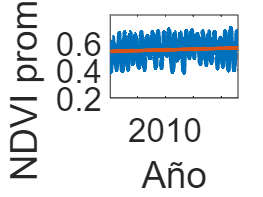


[a0,a1,ajuste] = m_reglin(1:filas,arr_promedio_dia);

 figure;
plot(t,arr_promedio_dia,t,ajuste,'LineWidth',2);
%plot(t,arr_promedio_dia);
%xlim([1 365]);
ylim([0.2 0.8]);
%title('NDVI promedio x día del año 2022')
xlabel('Año')
ylabel('NDVI promedio')
ax = gca;
ax.FontSize=16;

Mostrar mapa del promedio por pixel del periodo de estudio 

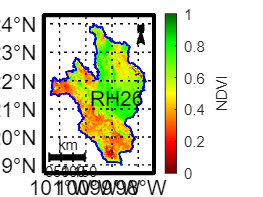

m1 = m_mean_3dpp(arr_ndvi);
m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,m1,"",[0 1],ndvi_colormap,"NDVI");
m_dibujar_kml(dir_data,"RH26",1,"b","RH26");

 ax = gca;
 exportgraphics(ax,"img/m_promedio_ndvi.png",'Resolution',300) 

Mostrar mapa de la desviación estandar por pixel del periodo de estudio 

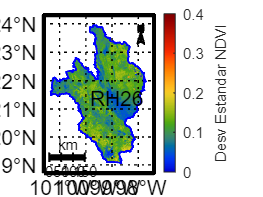

m1std = m_std_3dpp(arr_ndvi);
m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,m1std,"Desviación estandar de NDVI del 2000 al 2022",[0 0.4], m_colmap('jet'),"Desv Estandar NDVI");
m_dibujar_kml(dir_data,"RH26",1,"b","RH26");

 ax = gca;
 exportgraphics(ax,"img/desv_estandar.png",'Resolution',300) 

Mostrar mapa del coeficiente de variación por pixel del periodo de estudio 2022

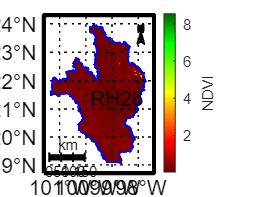

m1cv = m1std./m1;
m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,m1cv,"Coeficiente de variacion de NDVI del 2000 al 2022",[],ndvi_colormap,"NDVI");
m_dibujar_kml(dir_data,"RH26",1,"b","RH26");

 ax = gca;
 exportgraphics(ax,"img/coef_var.png",'Resolution',300) 

Regresión lineal por pixel del periodo de estudio 2022

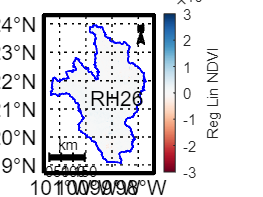


M = arr_ndvi;
tam_arr = size(M);
M = permute(M,[1 3 2]);

ma0 = zeros( tam_arr(1),tam_arr(2));
ma1 = zeros(tam_arr(1),tam_arr(2));

tmp_x = 1:tam_arr(3);

 for i=1:tam_arr(1)
     for j=1:tam_arr(2)
         [ma0(i,j),ma1(i,j),yaj] = m_reglin(tmp_x,M(i,:,j));
     end
 end
 ma1(area_estudio==false)=nan;

 m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ma1,"Regresión lineal de NDVI del 2000 al 2022",[-0.003 0.003], flipud(m_colmap('diverging',256)) ,"Reg Lin NDVI");
 m_dibujar_kml(dir_data,"RH26",1,"b","RH26");
 %m_dibujar_otras_areas(dir_data);

 ax = gca;
 exportgraphics(ax,"img/reg_lin.png",'Resolution',300) 

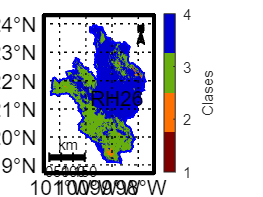

%contar pixeles
m1p = zeros(size(m1));

m1p(m1 == 0)=1;
m1p(m1 > 0 & m1 <=0.2) = 2;
m1p(m1 > 0.2 & m1<=0.5) = 3;
m1p(m1 > 0.5) = 4;

c1 = numel(find(m1p==1));
c2 = numel(find(m1p==2));
c3 = numel(find(m1p==3));
c4 = numel(find(m1p==4));

% pcolor(m1p); shading interp;
% colorbar;

pc1 = calidad_total / c1;
pc2 = calidad_total / c2;
pc3 = calidad_total / c3;
pc4 = calidad_total / c4;


m1p(area_estudio==false)=NaN;
 m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,m1p,"",[], flipud(m_colmap('jet',4)) ,"Clases");
 m_dibujar_kml(dir_data,"RH26",1,"b","RH26");
 %m_dibujar_otras_areas(dir_data);
 
 ax = gca;
 exportgraphics(ax,"img/clasificacion.png",'Resolution',300) 